# Example 4

#### Problem OCP:


$$\min_{{x}(t),{u}(t),t_f} -x_1(t_f)$$


subject to:


$$
 \dot{{x}_1}(t) = x_2(t) + u_1(t), \quad \dot{{x}_2}(t) = u_2(t), $$



$${x}_1(0)=0, \quad x_2(0)=0,  \quad t_f = 12$$



$$u_1(t)^2+u_2(t)^2 = 1 
$$


The analytical solution to this problem is 

$u_1(t) = \frac{1}{\sqrt{1+(T-t)^2}}$,    $u_2(t)=\frac{T-t}{\sqrt{1+(T-t)^2}}$

which we can use for comparison.

## Implementation:

clear all
close all

### Load Parameters

CONSTANTS.N = 5;
CONSTANTS.T = 12;

### Initial Guess

N = CONSTANTS.N; 
x1 = ones(N+1,1);
x2 = ones(N+1,1);
u1 = ones(N+1,1);
u2 = ones(N+1,1);
x0 = [x1;x2;u1;u2];

### Linear Constraints and UL bounds

A=[]; b=[]; Aeq=[]; beq=[]; lb=[]; ub=[]; 

### Optimize (fmincon)

options = optimoptions(@fmincon,'Algorithm','sqp','MaxFunctionEvaluations',300000);
tic
[x,f] = fmincon(@(x)costfun(x,CONSTANTS),x0,A,b,Aeq,beq,lb,ub,@(x)nonlcon(x,CONSTANTS),options);


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


toc

Elapsed time is 0.220402 seconds.


### Plot

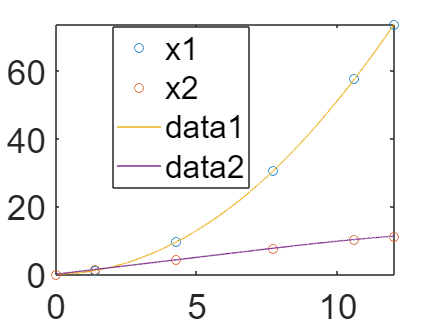

N = CONSTANTS.N;
T = CONSTANTS.T;
x1 = x(1:N+1);
x2 = x(N+2:2*N+2);
u1 = x(2*N+3:3*N+3);
u2 = x(3*N+4:end);
u1opt = @(t) 1./(sqrt(1+(T-t).^2));
u2opt = @(t) (T-t)./(sqrt(1+(T-t).^2));

[tnodes,w,Diff] = LGL_PS(CONSTANTS.N,CONSTANTS.T);
t = 0:0.001:CONSTANTS.T;

figure
plot(tnodes,x1,'o'); hold on
plot(tnodes,x2,'o')
legend('x1','x2')
plot(t,LagrangePoly(x1,tnodes,t));
plot(t,LagrangePoly(x2,tnodes,t));

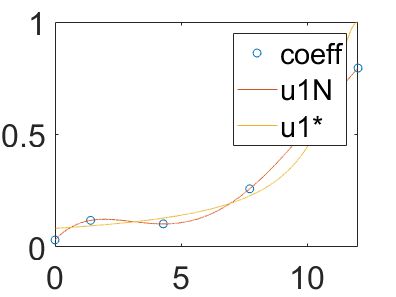


figure
plot(tnodes,u1,'o'); hold on
plot(t,LagrangePoly(u1,tnodes,t)); 
plot(t,u1opt(t));
legend('coeff','u1N','u1*')

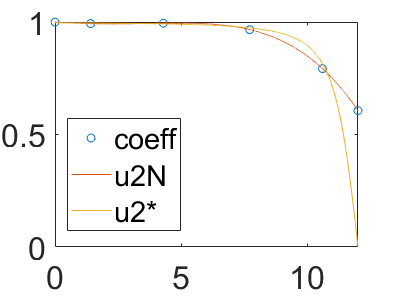

figure
plot(tnodes,u2,'o'); hold on
plot(t,LagrangePoly(u2,tnodes,t));
plot(t,u2opt(t));
legend('coeff','u2N','u2*')

### Cost function

function J = costfun(x,CONSTANTS)
%COSTFUN Summary of this function goes here
N = CONSTANTS.N; 

x1 = x(1:N+1);
x2 = x(N+2:2*N+2);
u1 = x(2*N+3:3*N+3);
u2 = x(3*N+4:end);

J = -x1(end);
end

### Nonlinear Constraint

function [c,ceq] = nonlcon(x,CONSTANTS)
%NONLCON Summary of this function goes here
%   Detailed explanation goes here
N = CONSTANTS.N; 

x1 = x(1:N+1);
x2 = x(N+2:2*N+2);
u1 = x(2*N+3:3*N+3);
u2 = x(3*N+4:end);

[tnodes,w,Diff] = LGL_PS(CONSTANTS.N,CONSTANTS.T);

dyn1 = x1'*Diff-x2'-u1';
dyn2 = x2'*Diff-u2';

nonlcon1 = u1.^2+u2.^2 - 1;

c=[];
ceq=[dyn1'; dyn2'; nonlcon1;x1(1);x2(1)];
end